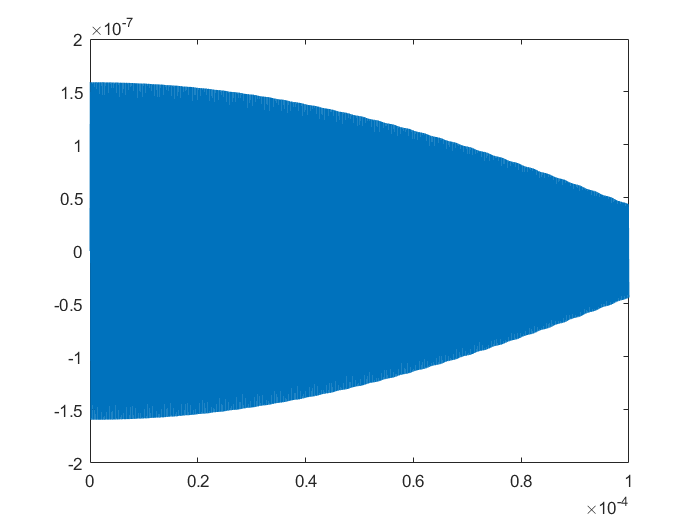


% % 1-D 1 particle(line2 to line23)
% % define parameters
% tau=1e-4;
% T=10;
% x0=5;
% v0=100;
% k=4*pi^2*4;
% N=T/tau;
% x=[];
% v=[];
% t=[];
% 
% % calculation
% x(1)=x0;
% v(1)=v0;
% t(1)=0;
% for i=1:N
%    t(i+1)=t(i)+tau;
%    v(i+1)=v(i)-k*x(i)*tau;
%    x(i+1)=x(i)+(v(i)+v(i+1))*tau/2;
% end
% plot(t,x);


% % 2-D 1 particle(line26 to line57)
% % define parameters
% tau=1e-4;%if tau is set not fine enough such as 1e-3, the simulation will fail
% T=10;
% vx0=100;
% vy0=500;
% x0=400;
% y0=100;
% k=100;
% N=T/tau;
% x=zeros(N,1);
% y=zeros(N,1);
% vx=zeros(N,1);
% vy=zeros(N,1);
% t=zeros(N,1);
% 
% % calculation
% x(1)=x0;
% y(1)=y0;
% vx(1)=vx0;
% vy(1)=vy0;
% t(1)=0;
% 
% for i=1:N
%     t(i+1)=t(i)+tau;
%     vx(i+1)=vx(i)-k*x(i)*tau;
%     vy(i+1)=vy(i)-k*y(i)*tau;
%     x(i+1)=x(i)+(vx(i)+vx(i+1))*tau/2;
%     y(i+1)=y(i)+(vy(i)+vy(i+1))*tau/2;
% end
% plot(t,x);
% plot(t,y);
% plot(x,y);



% 2-D 2 particles(line62 to line156)
% 
% NOte:
% tau=1e-2;T=1000;k=10000;kq=500 will go wrong
% however, tau=1e-3;T=1000;k=10000;kq=500 is able to work

% define parameters
mp=1.67e-27;
m=40*mp;
Q=1.6e-19;
epsilon=8.854e-12;
kq=Q^2/(4*pi*epsilon);
w1=2*pi*5e6;
w2=2*pi*0.2e6;
k1=m*w1^2;
k2=m*w2^2;

% time scale
tau=1e-9;
N=1e5;
T=N*tau;

% initial parameters
l1=(Q^2/(2*m*w1^2*pi*epsilon))^(1/3);
U1=m*w1^2*l1^2/4+Q^2/(4*pi*epsilon*l1);
l2=(Q^2/(2*m*w2^2*pi*epsilon))^(1/3);
U2=m*w2^2*l2^2/4+Q^2/(4*pi*epsilon*l2);
U=U1-U2;
vt=sqrt(2*U/m);
r10=[0,l2/2];
r20=-r10;
v10=[5,5];
v20=[0,0];
% k=10;
% kq=500;
r=zeros(N,2,2);
v=zeros(N,2,2);
t=zeros(1,N);
d=zeros(1,N);
E=zeros(1,N);
% r=[];
% v=[];
% t=[];
% d=[];
a=[];
t(1)=0;
% format x(time,order of the particle,spacial dimension)

% calculation
r(1,1,:)=r10;
r(1,2,:)=r20;
v(1,1,:)=v10;
v(1,2,:)=v20;
d(1)=sqrt((r(1,1,1)-r(1,2,1))^2+(r(1,1,2)-r(1,2,2))^2);
E(1)=m/2*(v(1,1,1)^2+v(1,1,2)^2+v(1,2,1)^2+v(1,2,2)^2)+...
    k1/2*(r(1,1,1)^2+r(1,2,1)^2)+k2/2*(r(1,1,2)^2+r(1,2,2)^2)+...
    kq*(1/d(1));

for i=2:N
    t(i)=t(i-1)+tau;
    d(i)=sqrt((r(i-1,1,1)-r(i-1,2,1))^2+(r(i-1,1,2)-r(i-1,2,2))^2);
%     a(1,1,:)=-k*r(i,1,:)+kq*(r(i,1,:)-r(i,2,:))/(d(i))^3;
%     a(1,2,:)=-k*r(i,2,:)+kq*(r(i,2,:)-r(i,1,:))/(d(i))^3;
    a(1,1,1)=-k1/m*r(i-1,1,1)+kq/m*(r(i-1,1,1)-r(i-1,2,1))/(d(i))^3;
    a(1,1,2)=-k2/m*r(i-1,1,2)+kq/m*(r(i-1,1,2)-r(i-1,2,2))/(d(i))^3;
    a(1,2,1)=-k1/m*r(i-1,2,1)+kq/m*(r(i-1,2,1)-r(i-1,1,1))/(d(i))^3;
    a(1,2,2)=-k2/m*r(i-1,2,2)+kq/m*(r(i-1,2,2)-r(i-1,1,2))/(d(i))^3;
    v(i,:,:)=v(i-1,:,:)+a*tau;
    r(i,:,:)=r(i-1,:,:)+(v(i,:,:)+v(i,:,:))*tau/2;
    E(i)=m/2*(v(i,1,1)^2+v(i,1,2)^2+v(i,2,1)^2+v(i,2,2)^2)+...
    k1/2*(r(i,1,1)^2+r(i,2,1)^2)+k2/2*(r(i,1,2)^2+r(i,2,2)^2)+...
    kq*(1/d(i));
end

plot(t,r(:,1,1));

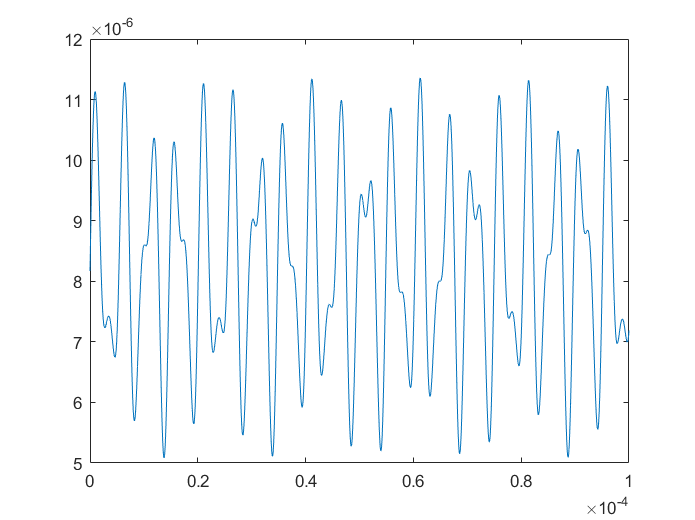

plot(t,r(:,1,2));

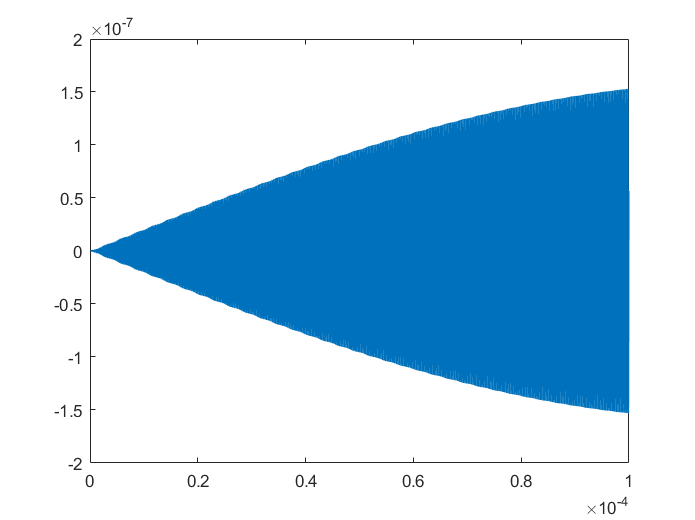

% hold on;
plot(t,r(:,2,1));

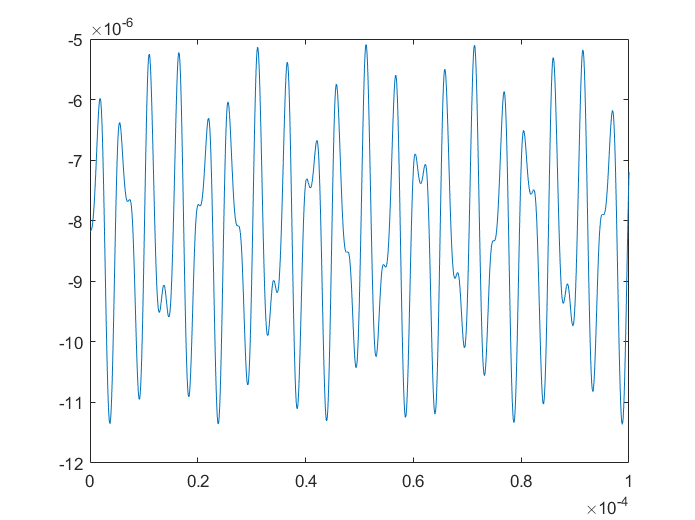

plot(t,r(:,2,2));

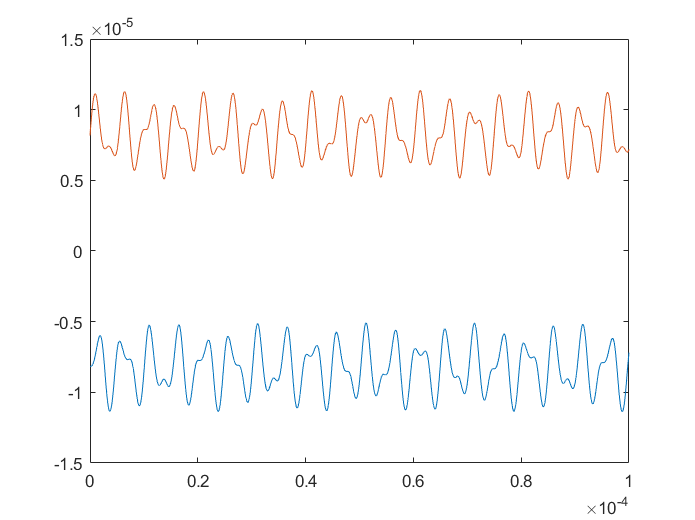


plot(t,r(:,2,2));
hold on;
plot(t,r(:,1,2));
hold off;

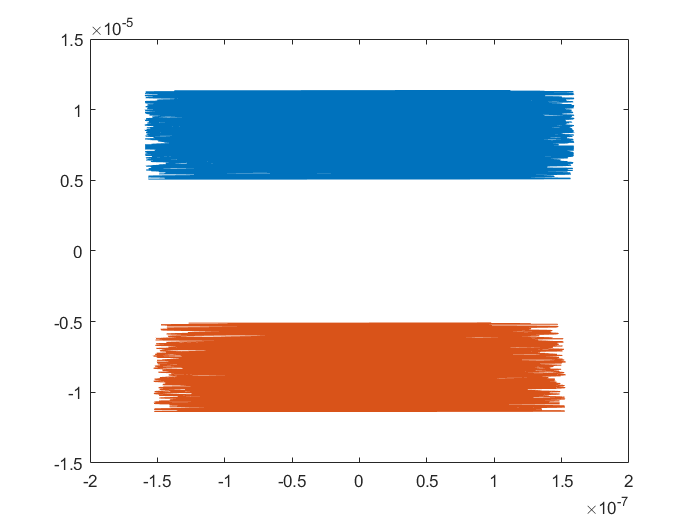


plot(r(:,1,1),r(:,1,2));
hold on;
plot(r(:,2,1),r(:,2,2));
hold off;

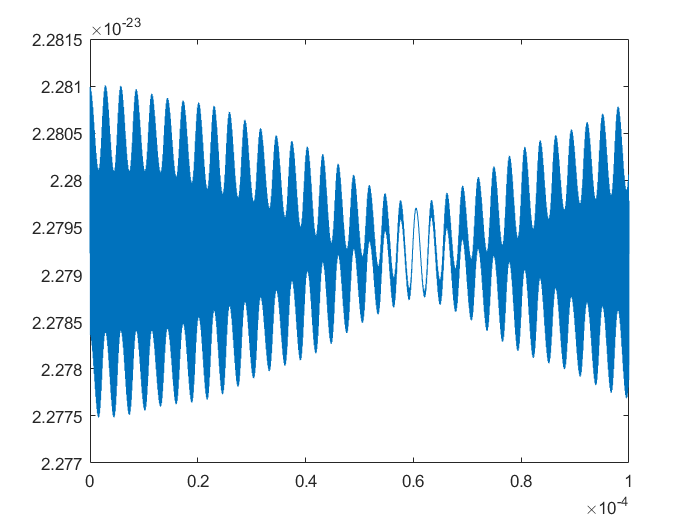

plot(t,E);

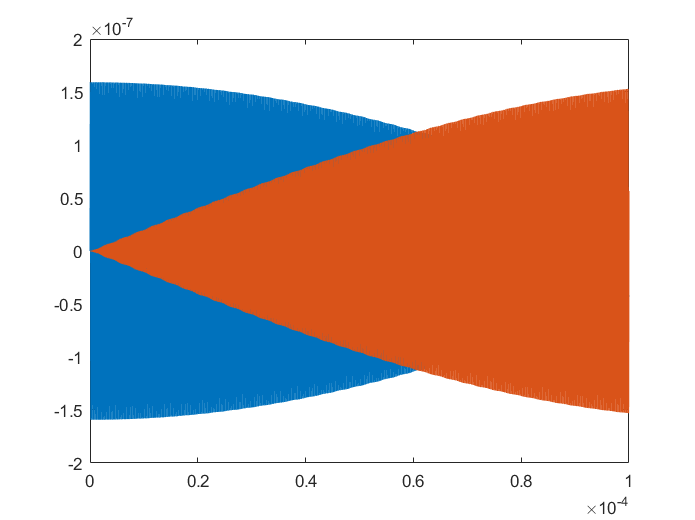


plot(t,r(:,1,1));
hold on
plot(t,r(:,2,1));
hold off

% plot(t,r(:,2,1));
% hold on;
% plot(t,r(:,1,1));
% hold off;




% % 2_D 3 particles(line161 to line250)
% 
% 
% mp=1.67e-27;
% m=40*mp;
% Q=1.6e-19;
% epsilon=8.854e-12;
% kq=Q^2/(4*pi*epsilon);
% w1=2*pi*5e6;
% w2=2*pi*0.2e6;
% k1=m*w1^2;
% k2=m*w2^2;
% 
% tau=1e-9;
% N=1e5;
% T=tau*N;
% l=(5*Q*Q/(16*m*w2^2*pi*epsilon))^(1/3);
% 
% 
% r10=[0,l];
% r20=[0,-l];
% r30=[0,0];
% v10=[0,0];
% v20=[0,0];
% v30=[30,-80];
% 
% r=zeros(N,3,2);
% v=zeros(N,3,2);
% t=zeros(1,N);
% d12=zeros(1,N);
% d23=zeros(1,N);
% d31=zeros(1,N);
% E=zeros(1,N);
% a=zeros(1,3,2);
% 
% r(1,1,:)=r10;
% r(1,2,:)=r20;
% r(1,3,:)=r30;
% v(1,1,:)=v10;
% v(1,2,:)=v20;
% v(1,3,:)=v30;
% d12(1)=sqrt((r(1,1,1)-r(1,2,1))^2+(r(1,1,2)-r(1,2,2))^2);
% d23(1)=sqrt((r(1,2,1)-r(1,3,1))^2+(r(1,2,2)-r(1,3,2))^2);
% d31(1)=sqrt((r(1,1,1)-r(1,3,1))^2+(r(1,1,2)-r(1,3,2))^2);
%     
% 
% 
% E(1)=E(1)+m/2*(v(1,1,1)^2+v(1,1,2)^2+v(1,2,1)^2+v(1,2,2)^2+v(1,3,1)^2+v(1,3,2)^2)+...
%     k1/2*(r(1,1,1)^2+r(1,2,1)^2+r(1,3,1)^2)+k2/2*(r(1,1,2)^2+r(1,2,2)^2+r(1,3,2)^2)+...
%     kq*(1/d12(1)+1/d23(1)+1/d31(1));
% 
% for i=2:N
%     t(i)=t(i-1)+tau;
%     d12(i)=sqrt((r(i-1,1,1)-r(i-1,2,1))^2+(r(i-1,1,2)-r(i-1,2,2))^2);
%     d23(i)=sqrt((r(i-1,2,1)-r(i-1,3,1))^2+(r(i-1,2,2)-r(i-1,3,2))^2);
%     d31(i)=sqrt((r(i-1,1,1)-r(i-1,3,1))^2+(r(i-1,1,2)-r(i-1,3,2))^2);
%     a(1,1,1)=-k1/m*r(i-1,1,1)+kq/m*((r(i-1,1,1)-r(i-1,2,1))/(d12(i))^3+(r(i-1,1,1)-r(i-1,3,1))/(d31(i))^3);
%     a(1,1,2)=-k2/m*r(i-1,1,2)+kq/m*((r(i-1,1,2)-r(i-1,2,2))/(d12(i))^3+(r(i-1,1,2)-r(i-1,3,2))/(d31(i))^3);
%     a(1,2,1)=-k1/m*r(i-1,2,1)+kq/m*((r(i-1,2,1)-r(i-1,1,1))/(d12(i))^3+(r(i-1,2,1)-r(i-1,3,1))/(d23(i))^3);
%     a(1,2,2)=-k2/m*r(i-1,2,2)+kq/m*((r(i-1,2,2)-r(i-1,1,2))/(d12(i))^3+(r(i-1,2,2)-r(i-1,3,2))/(d23(i))^3);
%     a(1,3,1)=-k1/m*r(i-1,3,1)+kq/m*((r(i-1,3,1)-r(i-1,2,1))/(d23(i))^3+(r(i-1,3,1)-r(i-1,1,1))/(d31(i))^3);
%     a(1,3,2)=-k2/m*r(i-1,3,2)+kq/m*((r(i-1,3,2)-r(i-1,2,2))/(d23(i))^3+(r(i-1,3,2)-r(i-1,1,2))/(d31(i))^3);
%     v(i,:,:)=v(i-1,:,:)+tau*a;
%     r(i,:,:)=r(i-1,:,:)+(v(i,:,:)+v(i,:,:))*tau/2;
%     E(i)=m/2*(v(i,1,1)^2+v(i,1,2)^2+v(i,2,1)^2+v(i,2,2)^2+v(i,3,1)^2+v(i,3,2)^2)+...
%     k1/2*(r(i,1,1)^2+r(i,2,1)^2+r(i,3,1)^2)+k2/2*(r(i,1,2)^2+r(i,2,2)^2+r(i,3,2)^2)+...
%     kq*(1/d12(i)+1/d23(i)+1/d31(i));
% 
% end
% 
% 
% 
% %.plot(t,v[:,0,0])
% %.plot(t,v[:,0,1])
% %.show()
% 
% plot(t,r(:,1,2));
% hold on
% plot(t,r(:,2,2));
% plot(t,r(:,3,2));
% hold off
% 
% plot(t,r(:,1,1));
% hold on
% plot(t,r(:,2,1));
% plot(t,r(:,3,1));
% hold off
% %.plot(t,r[:,0,0])
% %.plot(t,r[:,1,0])
% %.plot(t,r[:,2,0])
% %.show()
% 
% plot(r(:,1,1),r(:,1,2));
% plot(t,E);
% % plot(r[:,1,0],r[:,1,1])





% % 2-D 4 particles
% 
% mp=1.67e-27;
% m=40*mp;
% Q=1.6e-19;
% epsilon=8.854e-12;
% kq=Q^2/(4*pi*epsilon);
% w1=2*pi*5e6;
% w2=2*pi*0.2e6;
% k1=m*w1^2;
% k2=m*w2^2;
% 
% tau=2e-10;
% N=1e5;
% T=tau*N;
% l=(Q*Q/(4*m*(w2)^2*pi*epsilon))^(1/3);
% 
% 
% r10=[0,-1.4368*l];
% r20=[0,-0.45438*l];
% r30=[0,0.45438*l];
% r40=[0,1.4368*l];
% v10=[0,0];
% v20=[50,100];
% v30=[0,0];
% v40=[0,0];
% 
% r=zeros(N,4,2);
% v=zeros(N,4,2);
% t=zeros(1,N);
% d12=zeros(1,N);
% d13=zeros(1,N);
% d14=zeros(1,N);
% d23=zeros(1,N);
% d24=zeros(1,N);
% d34=zeros(1,N);
% E=zeros(1,N);
% a=zeros(1,3,2);
% 
% r(1,1,:)=r10;
% r(1,2,:)=r20;
% r(1,3,:)=r30;
% r(1,4,:)=r40;
% v(1,1,:)=v10;
% v(1,2,:)=v20;
% v(1,3,:)=v30;
% v(1,4,:)=v40;
% d12(1)=sqrt((r(1,1,1)-r(1,2,1))^2+(r(1,1,2)-r(1,2,2))^2);
% d13(1)=sqrt((r(1,1,1)-r(1,3,1))^2+(r(1,1,2)-r(1,3,2))^2);
% d14(1)=sqrt((r(1,1,1)-r(1,4,1))^2+(r(1,1,2)-r(1,4,2))^2);
% d23(1)=sqrt((r(1,2,1)-r(1,3,1))^2+(r(1,2,2)-r(1,3,2))^2);
% d24(1)=sqrt((r(1,2,1)-r(1,4,1))^2+(r(1,2,2)-r(1,4,2))^2);
% d34(1)=sqrt((r(1,3,1)-r(1,4,1))^2+(r(1,3,2)-r(1,4,2))^2);
%     
% 
% 
% E(1)=E(1)+m/2*(v(1,1,1)^2+v(1,1,2)^2+v(1,2,1)^2+v(1,2,2)^2+v(1,3,1)^2+v(1,3,2)^2+v(1,4,1)^2+v(1,4,2)^2)+...
%     k1/2*(r(1,1,1)^2+r(1,2,1)^2+r(1,3,1)^2+r(1,4,1)^2)+k2/2*(r(1,1,2)^2+r(1,2,2)^2+r(1,3,2)^2+r(1,4,2)^2)+...
%     kq*(1/d12(1)+1/d13(1)+1/d14(1)+1/d23(1)+1/d24(1)+1/d34(1));
% 
% for i=2:N
%     t(i)=t(i-1)+tau;
%     d12(i)=sqrt((r(i-1,1,1)-r(i-1,2,1))^2+(r(i-1,1,2)-r(i-1,2,2))^2);
%     d13(i)=sqrt((r(i-1,1,1)-r(i-1,3,1))^2+(r(i-1,1,2)-r(i-1,3,2))^2);
%     d14(i)=sqrt((r(i-1,1,1)-r(i-1,4,1))^2+(r(i-1,1,2)-r(i-1,4,2))^2);
%     d23(i)=sqrt((r(i-1,2,1)-r(i-1,3,1))^2+(r(i-1,2,2)-r(i-1,3,2))^2);
%     d24(i)=sqrt((r(i-1,2,1)-r(i-1,4,1))^2+(r(i-1,2,2)-r(i-1,4,2))^2);
%     d34(i)=sqrt((r(i-1,3,1)-r(i-1,4,1))^2+(r(i-1,3,2)-r(i-1,4,2))^2);
%     a(1,1,1)=-k1/m*r(i-1,1,1)+kq/m*((r(i-1,1,1)-r(i-1,2,1))/(d12(i))^3+(r(i-1,1,1)-r(i-1,3,1))/(d13(i))^3+(r(i-1,1,1)-r(i-1,4,1))/(d14(i))^3);
%     a(1,1,2)=-k2/m*r(i-1,1,2)+kq/m*((r(i-1,1,2)-r(i-1,2,2))/(d12(i))^3+(r(i-1,1,2)-r(i-1,3,2))/(d13(i))^3+(r(i-1,1,2)-r(i-1,4,2))/(d14(i))^3);
%     a(1,2,1)=-k1/m*r(i-1,2,1)+kq/m*((r(i-1,2,1)-r(i-1,1,1))/(d12(i))^3+(r(i-1,2,1)-r(i-1,3,1))/(d23(i))^3+(r(i-1,2,1)-r(i-1,4,1))/(d24(i))^3);
%     a(1,2,2)=-k2/m*r(i-1,2,2)+kq/m*((r(i-1,2,2)-r(i-1,1,2))/(d12(i))^3+(r(i-1,2,2)-r(i-1,3,2))/(d23(i))^3+(r(i-1,2,2)-r(i-1,4,2))/(d24(i))^3);
%     a(1,3,1)=-k1/m*r(i-1,3,1)+kq/m*((r(i-1,3,1)-r(i-1,1,1))/(d13(i))^3+(r(i-1,3,1)-r(i-1,2,1))/(d23(i))^3+(r(i-1,3,1)-r(i-1,4,1))/(d34(i))^3);
%     a(1,3,2)=-k2/m*r(i-1,3,2)+kq/m*((r(i-1,3,2)-r(i-1,1,2))/(d13(i))^3+(r(i-1,3,2)-r(i-1,2,2))/(d23(i))^3+(r(i-1,3,2)-r(i-1,4,2))/(d34(i))^3);
%     a(1,4,1)=-k1/m*r(i-1,4,1)+kq/m*((r(i-1,4,1)-r(i-1,1,1))/(d14(i))^3+(r(i-1,4,1)-r(i-1,2,1))/(d24(i))^3+(r(i-1,4,1)-r(i-1,3,1))/(d34(i))^3);
%     a(1,4,2)=-k2/m*r(i-1,4,2)+kq/m*((r(i-1,4,2)-r(i-1,1,2))/(d14(i))^3+(r(i-1,4,2)-r(i-1,2,2))/(d24(i))^3+(r(i-1,4,2)-r(i-1,3,2))/(d34(i))^3);   
%     v(i,:,:)=v(i-1,:,:)+tau*a;
%     r(i,:,:)=r(i-1,:,:)+(v(i,:,:)+v(i,:,:))*tau/2;
%     E(i)=m/2*(v(i,1,1)^2+v(i,1,2)^2+v(i,2,1)^2+v(i,2,2)^2+v(i,3,1)^2+v(i,3,2)^2+v(i,4,1)^2+v(i,4,2)^2)+...
%     k1/2*(r(i,1,1)^2+r(i,2,1)^2+r(i,3,1)^2+r(i,4,1)^2)+k2/2*(r(i,1,2)^2+r(i,2,2)^2+r(i,3,2)^2+r(i,4,2)^2)+...
%     kq*(1/d12(i)+1/d13(i)+1/d14(i)+1/d23(i)+1/d24(i)+1/d34(i));
% 
% end
% 
% 
% 
% %.plot(t,v[:,0,0])
% %.plot(t,v[:,0,1])
% %.show()
% 
% plot(t,r(:,1,2));
% hold on
% plot(t,r(:,2,2));
% plot(t,r(:,3,2));
% plot(t,r(:,4,2));
% hold off
% 
% %.plot(t,r[:,0,0])
% %.plot(t,r[:,1,0])
% %.plot(t,r[:,2,0])
% %.show()
% 
% plot(r(:,1,1),r(:,1,2));
% plot(t,E);
% % plot(r[:,1,0],r[:,1,1])
